# DC Motor Position: PID Controller Design

Key MATLAB commands used in this tutorial are: [`tf`](http://www.mathworks.com/help/toolbox/control/ref/tf.html) ,  [`step`](http://www.mathworks.com/help/toolbox/control/ref/step.html) ,  [`feedback`](http://www.mathworks.com/help/toolbox/control/ref/feedback.html)

From the main problem, the open-loop transfer function of the DC Motor is given as follows.


$$ P(s) = \frac {\Theta (s)}{V(s)} = \frac{K}{s ( (Js + b)(Ls + R) + K^2 )} \qquad \frac{rad}{V}  $$


The structure of the control system has the form shown in the figure below. 

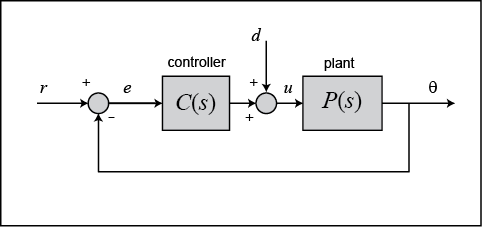

For the original problem setup and the derivation of the above equations, please refer to the[ DC Motor Position: System Modeling](http://ctms.engin.umich.edu/CTMS/index.php?example=MotorPosition&section=SystemModeling) page. 

For a 1-radian step reference, the design criteria are the following:

- Settling time less than 0.040 seconds

- Overshoot less than 16%

- No steady-state error, even in the presence of a step disturbance input

Now let's design a PID controller and add it into the system. Given below are a set of values for the parameters of our DC Motor and the definition of the plant transfer function. 

J = 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
R = 4;
L = 2.75E-6;
s = tf('s');
P_motor = K/(s*((J*s+b)*(L*s+R)+K^2));

Recall that the transfer function for a PID controller has the following form.


$$ C(s) = K_{p} + \frac {K_{i}} {s} + K_{d}s = \frac{K_{d}s^2 + K_{p}s + K_{i}} {s}  $$


In this live script, we will experiment with the gains of a PID controller to better understand the effects of each if its three terms, while ultimately producing a controller for our motor position system. 

## Proportional control

We will begin by considering only the P term of our PID controller. In this situation, the applied control is *proportional* to the error of our controlled variable, the motor position. In the following, one can employ the slider to vary the gain $K_P$ and observe the resulting effect on the system's closed-loop unit step response.

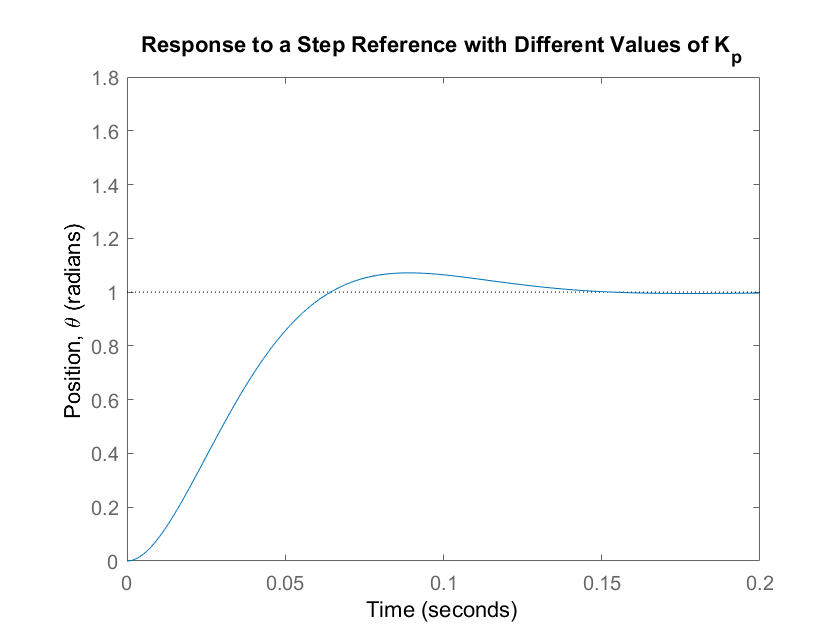

Kp =1;
C = Kp;
sys_cl = feedback(C*P_motor,1);
t = 0:0.001:0.2;
figure(1)
step(sys_cl,t)
axis([0 0.2 0 1.8])
ylabel('Position, \theta (radians)')
title('Response to a Step Reference with Different Values of K_p')

You should observe that the steady-state error is zero for all values of $K_P$. This is expected since the integrator in the plant makes the system type 1. Type 1 systems can track constant (step) inputs with zero steady-state error. In terms of the transient response, increasing $K_P$ makes the motor response faster but more oscillatory. This behavior is somewhat intuitive. A larger proportional gain means the same amount of error will result in the controller "pushing" harder. This larger control action gets the motor to its setpoint more quickly, but also results in the motor overshooting the commanded position. 

Let's also consider the system's response to a step disturbance. In this case, we will assume a reference of zero and look at how the system responds to the disturbance by itself. The `feedback` command can still be employed for generating the closed-loop transfer function where there is still negative feedback, however, now only the plant transfer function $P_{\textrm{motor}} \left(s\right)$ is in the forward path and the controller $C\left(s\right)$ is considered to be in the feedback path. Refer back to the block diagram at the top of this page to see the structure of the system. 

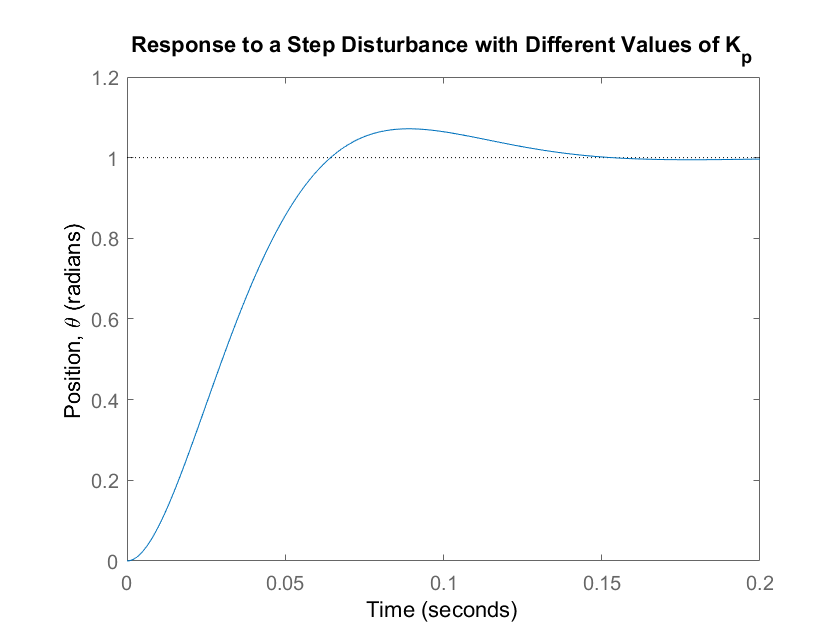

Kp =1;
C = Kp;
dist_cl = feedback(P_motor,C);
figure(2)
step(dist_cl, t)
axis([0 0.2 0 1.2])
ylabel('Position, \theta (radians)')
title('Response to a Step Disturbance with Different Values of K_p')

While the system had zero steady-state error for a step reference by itself, the resulting graph demonstrates the system has significant steady-state error when the disturbance is added. Recall, the response due to the reference and disturbance applied simultaneously is equal to the sum of the two generated graphs. This follows from the property of **superposition** that holds for linear systems. Therefore, to have zero steady-state error in the presence of a disturbance, we need the disturbance response to decay to zero. The larger the value of $K_P \;$the smaller the steady-state error due to the disturbance is, but it never reaches zero. In conclusion, a proportional controller is unable to satisfy all of the given design requirements at the same time. 

## PI control

Since the proportional controller was unable to meet all of our design requirements, let's add an I term to our controller. The integral term adds a component to the control that is proportional to the integral of the error such that control effort builds in the presence of error with consistent sign. The effect of this "summing" of the error by the integral term is that it tends to help reduce a system's steady-state error. This could be beneficial since we saw in the previous section that, even with a large proportional gain, the steady-state error never reached zero when a continuous disturbance was present. Using the numeric slider in the following interactive script, vary the value of the integral gain $K_i$ and observe the change in the response of the system to the reference and the disturbance. Based on the previous investigation, here we will keep the proportional gain constant at 25. 

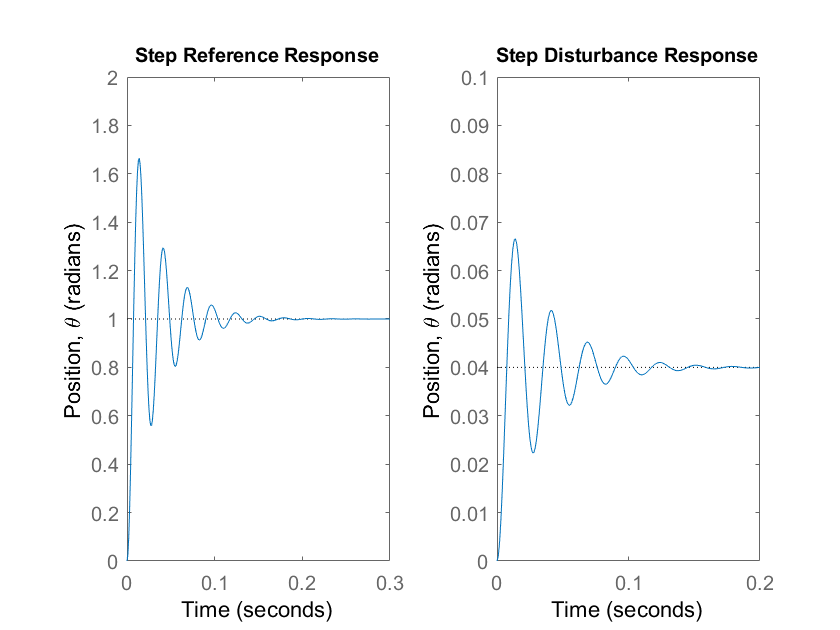

Kp = 25;
Ki = 100;
C= Kp + Ki/s;
sys_cl = feedback(C*P_motor,1);
t = 0:0.001:0.30;
figure(3)
subplot(1,2,2)
subplot(1,2,1)
step(sys_cl, t);
axis([0 0.3 0 2])
ylabel('Position, \theta (radians)');
title('Step Reference Response'); 
subplot(1,2,2)
dist_cl = feedback(P_motor,C);
step(dist_cl, t)
axis([0 0.2 0 0.1])
ylabel('Position, \theta (radians)')
title('Step Disturbance Response')

You should have observed that the integral control has reduced the steady-state error to zero, even when a step disturbance is present; that was the goal for adding the integral term. For the response to the step reference, the response doesn't change significantly, though the amount of oscillation increases slightly as $K_i$ is made larger. However, the response due to the disturbance changes significantly as the integral gain $K_i$ is varied. Specifically, the larger the value of $K_i$ employed, the faster the error decays to zero. Unfortunately, the PI controller is still not able to meet all of the provided requirements.

## PID control

In our drive to meet all of the provided system requirements, we will now add a D term to the controller such that we have all three terms of the PID controller. The derivative term adds a component to the control that is proportional to the derivative of the error. Since the D term is based on the rate with which the error is changing, it allows the controller to anticipate changes in error. This tends to have a dampening effect on the closed-loop system's response. In the following, we will maintain the same constant value of $K_p$ used before and will choose $K_i$ to equal 500. Use the slider to vary the $K_d$ gain and observe the resulting effect the response to the step reference and step disturbance. 

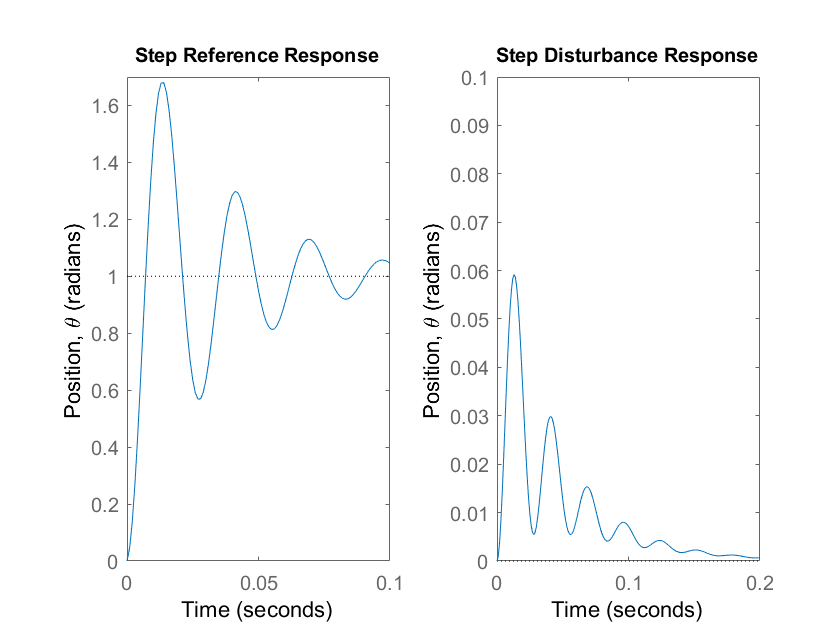

Kp = 25;
Ki = 500;
Kd = 0.01;
C = Kp + Ki/s + Kd*s;
sys_cl = feedback(C*P_motor,1);
t = 0:0.001:0.1;
figure(4)
subplot(1,2,2)
subplot(1,2,1)
step(sys_cl, t)
axis([0 0.1 0 1.7])
ylabel('Position, \theta (radians)')
title('Step Reference Response')
subplot(1,2,2)
dist_cl = feedback(P_motor,C);
t = 0:0.001:0.2;
step(dist_cl, t)
axis([0 0.2 0 0.1])
ylabel('Position, \theta (radians)')
title('Step Disturbance Response')

As expected, you should have observed that increasing the $K_d$ gain decreased the oscillation in response to both the reference and the disturbance. This reduces the system's overshoot and settling time. This preliminary investigation seems to indicate that a PID controller, with appropriately chosen gains, can meet the provided specifications. Recall our design requirements for a 1-radian step reference: 

- Settling time less than 0.040 seconds

- Overshoot less than 16%

- No steady-state error, even in the presence of a step disturbance input

The MATLAB command `stepinfo,` as shown below, provides the characteristics of a system's step response. The following is specifically for the closed-loop system's response to a unit step in the reference.

stepinfo(sys_cl)

ans = struct with fields:
        RiseTime: 0.0049
    SettlingTime: 0.1278
     SettlingMin: 0.5663
     SettlingMax: 1.6823
       Overshoot: 68.2334
      Undershoot: 0
            Peak: 1.6823
        PeakTime: 0.0138


Now let's use the property of superposition to generate the closed-loop response of the system to the simultaneous application of a unit step reference and unit step disturbance. You can then use the numerical sliders to tune each of the three terms of the PID controller while attempting to achieve our three design requirements. One approach to tuning the gains that you can employ is as follows: (1) use $K_P$ to increase the speed of response, (2) use $K_d$ to reduce the oscillation, and (3) use $K_i$ to increase the speed with which the steady-state error is driven to zero. 

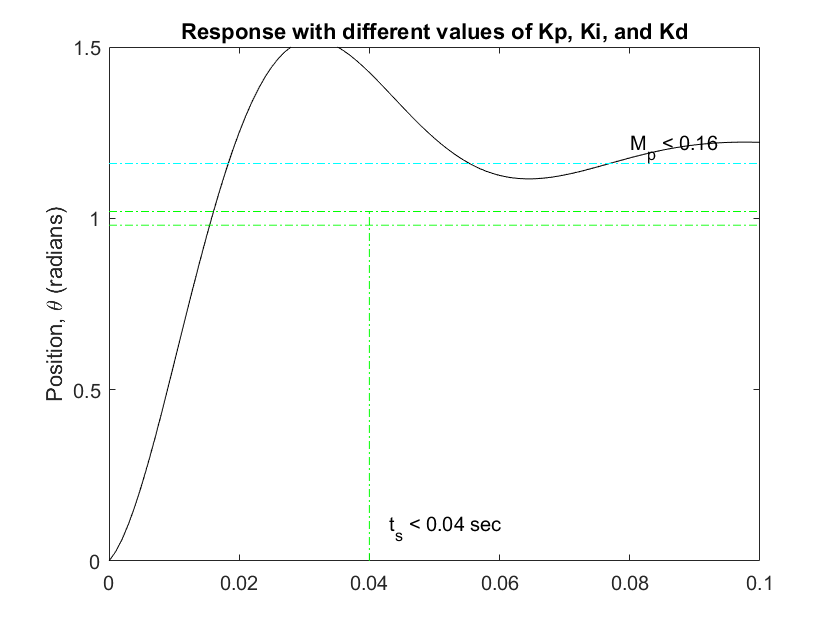

Kp = 5;
Ki =700;
Kd = 0.01;
C = Kp + Ki/s + Kd*s;
sys_cl = feedback(C*P_motor,1);
dist_cl = feedback(P_motor,C);
t = 0:0.001:0.1;
[yr,t] = step(sys_cl, t);
[yd,t] = step(dist_cl, t);
figure(5);
plot(t,yr+yd,'k')
axis([0 0.1 0 1.5])
ylabel('Position, \theta (radians)')
title('Response with different values of Kp, Ki, and Kd')
displayReqs(0.040,0.16)

## Conclusion

Based on experimentation with the above interactive script, you should be able to find a set of controller gains that meet all three of our design requirements. One choice that will work is $K_p =30$, $K_i =900$, and $K_d =0\ldotp 20$, though there are many others. 

*The following function is used in the script above.*

function displayReqs(settleTime,overshoot) 
hold on;
plot([0 0.1],[1.02 1.02],'g-.');
plot([0 0.1],[0.98 0.98],'g-.');
plot([settleTime settleTime],[0 1.02],'g-.')
text(settleTime+0.003,0.1,['t_s < ',num2str(settleTime),' sec']);
plot([0 0.1],[(1+overshoot) (1+overshoot)],'c-.');
text(0.08,1.05+overshoot,['M_p < ',num2str(overshoot)]);
hold off;
end